# Dynamics Final Project

# Rollercoaster

## Olivia Jo Bradley

% Problem
clc
clearvars

HEIGHT OF THE START

%change start height
h = 75;

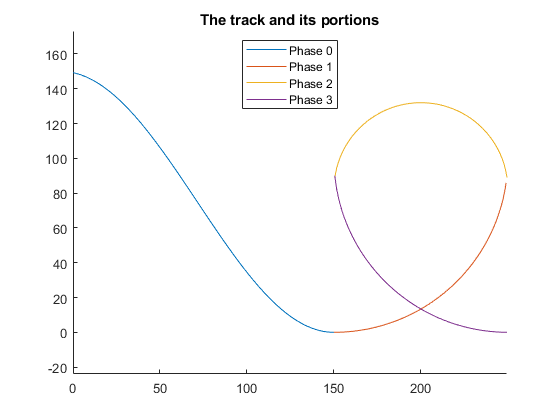

%plotting the coaster desired track
x0 = [0:1:150];
part0 = h*cos(x0/50 + (pi-3)) + h;
x1 = [150:1:249.5];
part1 = -sqrt(100^2-(x1-150).^2)+100;
x2 = [150.5:1:249.5];
part2 = sqrt(50^2-(x2-200).^2)+82;
x3 = [150.5:1:250];
part3 = -sqrt(100^2-(x3-250).^2)+100;
% f = [0:1:250]
figure()
hold on
plot (x0, part0)
plot (x1, part1)
plot (x2, part2)
plot (x3, part3)
axis("equal")
hold off
legend("Phase 0","Phase 1","Phase 2","Phase 3", "Location","best")
title("The track and its portions")

% initial position
x0 = 1; % m
y0 = h*2; % m

% initial velocity
dx = 1;
dy = 1;

% Solve for phase 0, phase 1, phase 2, and phase 3 motion using separate ode45 calls 
% pack initial conditions into column vector
Z_0p0 = [x0, dx, y0, dy];

Tph0_span = [0, 100];      % define time span for phase 0 ode calc
options0 = odeset('Events', @event_stop1);

[tph0, yph0] = simPhase0(Z_0p0, Tph0_span, h);

%Inital conditions for phase 1 = end points for phase 0
Z_0p1 = [yph0(end,1), yph0(end,2), yph0(end,3), yph0(end,4)];

Tph1_span = [tph0(end), 100];
options1 = odeset('Events', @event_stop1);

[tph1, yph1] = simPhase1(Z_0p1, Tph1_span);


% %Inital conditions for phase 2 = end points for phase 1
%Z_0p2 = [yph1(end,1), yph1(end,2), yph1(end,3), yph1(end,4)]
Z_0p2 = [249, -2*yph1(end,2), yph1(end,3), yph1(end,4)]

Z_0p2 =   249.0000   -5.8941  106.3122   30.5459


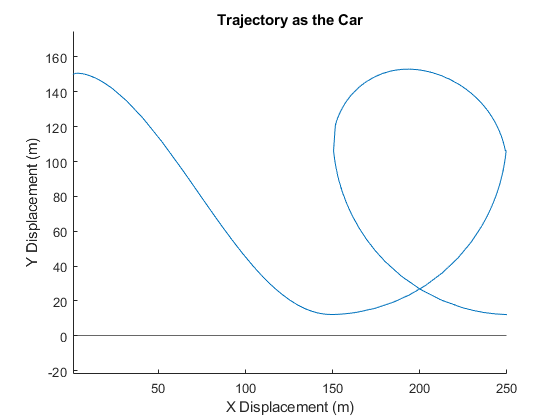


Tph2_span = [tph1(end), 100];
options2 = odeset('Events', @event_stop2);

[tph2, yph2] = simPhase2(Z_0p2, Tph2_span);

% Inital conditions for phase 3 = end points for phase 2
Z_0p3 = [150.5, yph1(end,2), yph1(end,3),-yph1(end,4)];

Tph3_span = [tph2(end), 100];
options3 = odeset('Events', @event_stop3);
[tph3, yph3] = simPhase3(Z_0p3, Tph3_span);

t = [tph0;tph1;tph2; tph3];
p = [yph0;yph1;yph2; yph3];

% plotting
x = p(:,1);
y = p(:,3);
figure()
hold on
plot(x,y)
yline(0)
hold off
title('Trajectory as the Car')
xlabel("X Displacement (m)")
ylabel("Y Displacement (m)")
axis("equal")

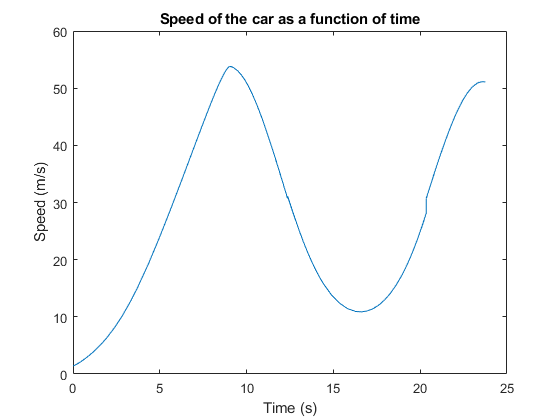


speeed = sqrt(p(:,2).^2 + p(:,4).^2);
plot(t, speeed)
title('Speed of the car as a function of time')
xlabel("Time (s)")
ylabel("Speed (m/s)")

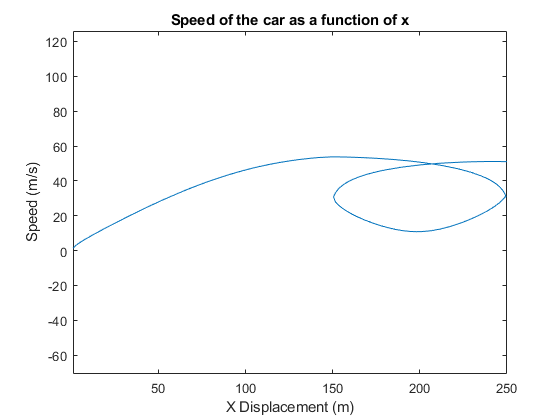



speeed = sqrt(p(:,2).^2 + p(:,4).^2);
plot(x, speeed)
title('Speed of the car as a function of x')
xlabel("X Displacement (m)")
ylabel("Speed (m/s)")
axis("equal")


disp("Phase 0 ends at " + tph0(end) + " seconds")

Phase 0 ends at 9.0296 seconds


disp("Phase 1 ends at " + tph1(end) + " seconds")

Phase 1 ends at 12.3622 seconds


disp("Phase 2 ends at " + tph2(end) + " seconds")

Phase 2 ends at 20.3482 seconds


disp("Phase 3 ends at " + tph3(end) + " seconds")

Phase 3 ends at 23.759 seconds




m = 500; % kg
g = 9.8

g = 9.8000

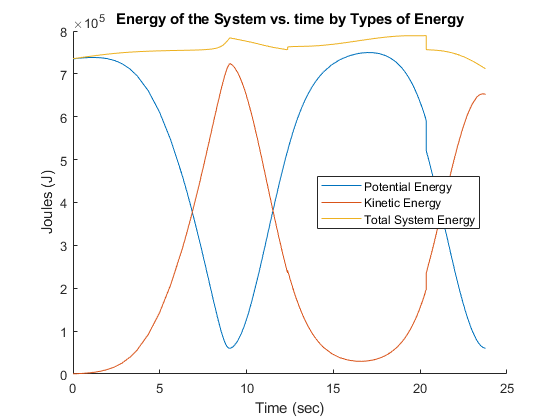

% Energy Plots m*g*h
% Potential Energy mgh
PEp0 = m*g*(yph0(:,3));
PEp1 = m*g*(yph1(:,3));
PEp2 = m*g*(yph2(:,3));
PEp3 = m*g*(yph3(:,3));

PEt = [PEp0;PEp1;PEp2;PEp3];

% Kinetic Energy 1/2 mv^2
KEp0 = 0.5*m*(yph0(:,2)).^2 + 0.5*m*(yph0(:,4)).^2;
KEp1 = 0.5*m*(yph1(:,2)).^2 + 0.5*m*(yph1(:,4)).^2;
KEp2 = 0.5*m*(yph2(:,2)).^2 + 0.5*m*(yph2(:,4)).^2;
KEp3 = 0.5*m*(yph3(:,2)).^2 + 0.5*m*(yph3(:,4)).^2;

KEt = [KEp0;KEp1;KEp2;KEp3];

totalPE = PEt;
totalKE = KEt;
totalE = totalPE + totalKE;

figure ()
hold on
plot(t,totalPE)
plot(t,totalKE)
plot(t,totalE)
legend('Potential Energy','Kinetic Energy','Total System Energy', 'Location',"best")
title('Energy of the System vs. time by Types of Energy')
xlabel ('Time (sec)')
ylabel ('Joules (J)')
hold off

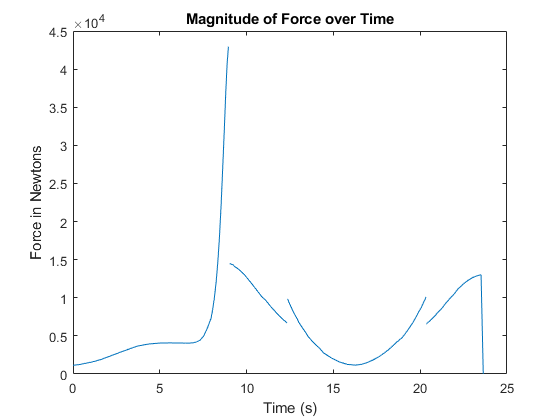


% Force Plots
vx = p(:,2);
vy = p(:,4);
ax = zeros(1,length(vx)-1);
ay = zeros(1,length(vy)-1);
for i=[1:length(ax)-1]
    ax(i) = (vx(i+1) - vx(i))/(t(i+1) - t(i));
    ay(i) = (vy(i+1) - vy(i))/(t(i+1) - t(i));
end
m = 500;
a = sqrt(ax.^2 + ay.^2);
F = m.*a;
plot(t(1:end-1), F)
title ("Magnitude of Force over Time")
xlabel("Time (s)")
ylabel("Force in Newtons")

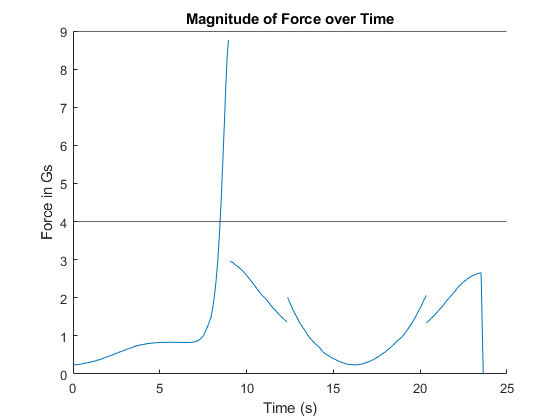


figure()
passoutforce = 4;
deadforce = 9;
hold on
plot(t(1:end-1), F/(m*g))
yline(passoutforce)
yline(deadforce)
hold off
title ("Magnitude of Force over Time")
xlabel("Time (s)")
ylabel("Force in Gs")


% figure()
% s = p(:,3)/h * sqrt(2)
% R = 200
% bigS = @(x) sin(pi/2 *x.^2)
% S = integral(bigS, 0, length(t))
% forces = 2.*pi.*(s/R.^2).* mean(totalE) - 2.*pi.*(s/R).*m.*g.*S.*(s/R) + m.*g.*cos((pi.*s.^2)/(2.*R.^2));
% passoutforce = 4;
% deadforce = 9;
% hold on
% plot(t, forces, "*")
% yline(passoutforce)
% yline(deadforce)
% hold off

PHASE 0

function [t,p] = simPhase0(init, tspan, h)
    
    % time span
      
    % simulation params, used in ODE funcs
    g = 9.8;
    m = 500; % kg
    A = 4.0; % m^2
    Cd = 0.01; % coeff
    rho = 1.02; % kg/m^3
    
    
    c = rho*Cd*A/(2*m);
   
x = sym('x');
y = @(x)  h*cos(x/50 + (pi-3)) + h;

a = matlabFunction(diff(y(x)));

b = matlabFunction(diff(a(x)));
    
    % use ode45 and stop at event
    options0 = odeset('Events', @eventFcn0, 'RelTol', 1e-3);
    [t,p] = ode45(@f,tspan,init, options0);

    % define ODEs
    function dpdt = f(~,p)
Q = [1 0 0 0 0;
     0 1 0 0 0;
     0 0 1 0 a(p(1))/(m*sqrt(1+a(p(1))^2));
     0 0 0 1 -1/(m*sqrt(1+a(p(1))^2));
     0 0 a(p(1)) -1 0];

V = norm([p(2) p(4)]);

r = [p(2), p(4), -c*V^2/(sqrt(1+a(p(1))^2)), -c*a(p(1))*V^2/(sqrt(1+a(p(1))^2))-g, -b(p(1))*p(2)^2]';
    
z = (Q\r)';


        dx = z(1);  % x velocity
        ddx = z(3);    % x accel
        dy = z(2);  % y velocity
        ddy = z(4);    % y accel
        
        % pack ODEs into column vector
        dpdt = [dx ddx dy ddy]';
    end
    
    function [position,isterminal,direction] = eventFcn0(~,p)
        position = 150 - p(1); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end

PHASE 1

function [t,p] = simPhase1(init, tspan)
    
    % time span
      
    % simulation params, used in ODE funcs
    g = 9.8;
    m = 500; % kg
    A = 4.0; % m^2
    Cd = 0.1; % coeff
    rho = 1.02; % kg/m^3
    h = 100;
    
    c = rho*Cd*A/(2*m);
   
x = sym('x');
y = @(x) -sqrt(100^2-(x-150)^2)+100;

a = matlabFunction(diff(y(x)));

b = matlabFunction(diff(a(x)));
    
    % use ode45 and stop at event
    options1 = odeset('Events', @eventFcn1, 'RelTol', 1e-3);
    [t,p] = ode45(@f,tspan,init, options1);

    % define ODEs
    function dpdt = f(~,p)
Q = [1 0 0 0 0;
     0 1 0 0 0;
     0 0 1 0 a(p(1))/(m*sqrt(1+a(p(1))^2));
     0 0 0 1 -1/(m*sqrt(1+a(p(1))^2));
     0 0 a(p(1)) -1 0];

V = norm([p(2) p(4)]);

r = [p(2), p(4), -c*V^2/(sqrt(1+a(p(1))^2)), -c*a(p(1))*V^2/(sqrt(1+a(p(1))^2))-g, -b(p(1))*p(2)^2]';
    
z = (Q\r)';


        dx = z(1);  % x velocity
        ddx = z(3);    % x accel
        dy = z(2);  % y velocity
        ddy = z(4);    % y accel
        
        % pack ODEs into column vector
        dpdt = [dx ddx dy ddy]';
    end
    
    function [position,isterminal,direction] = eventFcn1(~,p)
        position = 249.5 - p(1); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end

PHASE 2

function [t,p] = simPhase2(init, tspan)
    
    % time span
   
    % simulation params, used in ODE funcs
    g = 9.8;
    m = 500; % kg
    A = 4.0; % m^2
    Cd = 0.1; % coeff
    rho = 1.02; % kg/m^3
    
    c = rho*Cd*A/(2*m);
   
x = sym('x');
y = @(x) sqrt(50^2-(x-200)^2)+81;
    
a = matlabFunction(diff(y(x)));

b = matlabFunction(diff(a(x)));
    
    % use ode45 and stop at event
    options2 = odeset('Events', @eventFcn2, 'RelTol', 1e-3);
    [t,p] = ode45(@f,tspan,init,options2);

    % define ODEs
    function dpdt = f(~,p)
Q = [1 0 0 0 0;
     0 1 0 0 0;
     0 0 1 0 a(p(1))/(m*sqrt(1+a(p(1))^2));
     0 0 0 1 -1/(m*sqrt(1+a(p(1))^2));
     0 0 a(p(1)) -1 0];

V = norm([p(2) p(4)]);

r = [p(2), p(4), -c*V^2/(sqrt(1+a(p(1))^2)), -c*a(p(1))*V^2/(sqrt(1+a(p(1))^2))-g, -b(p(1))*p(2)^2]';
    
z = (Q\r)';


        dx = z(1);  % x velocity
        ddx = z(3);    % x accel
        dy = z(2);  % y velocity
        ddy = z(4);    % y accel
        
        % pack ODEs into column vector
        dpdt = [dx ddx dy ddy]';
    end
    
    function [position,isterminal,direction] = eventFcn2(~,p)
        position = 151.5-p(1); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end

PHASE 3

function [t,p] = simPhase3(init, tspan)
    
    % time span
     
    % simulation params, used in ODE funcs
    g = 9.8;
    m = 500; % kg
    A = 4.0; % m^2
    Cd = 0.01; % coeff
    rho = 1.02; % kg/m^3
    B = 0.361; % Estimated Value 
    h = 100;
    L = 500;
    
    c = rho*Cd*A/(2*m);
   
x = sym('x');
y = @(x) -sqrt(100^2-(x-250)^2)+100;
    
a = matlabFunction(diff(y(x)));

b = matlabFunction(diff(a(x)));
    
    % use ode45 and stop at event
    options3 = odeset('Events', @eventFcn3, 'RelTol', 1e-3);
    [t,p] = ode45(@f,tspan,init,options3);

    % define ODEs
    function dpdt = f(~,p)
Q = [1 0 0 0 0;
     0 1 0 0 0;
     0 0 1 0 a(p(1))/(m*sqrt(1+a(p(1))^2));
     0 0 0 1 -1/(m*sqrt(1+a(p(1))^2));
     0 0 a(p(1)) -1 0];

V = norm([p(2) p(4)]);

r = [p(2), p(4), -c*V^2/(sqrt(1+a(p(1))^2)), -c*a(p(1))*V^2/(sqrt(1+a(p(1))^2))-g, -b(p(1))*p(2)^2]';
    
z = (Q\r)';

        dx = z(1);  % x velocity
        ddx = z(3);    % x accel
        dy = z(2);  % y velocity
        ddy = z(4);    % y accel
        
        % pack ODEs into column vector
        dpdt = [dx ddx dy ddy]';
    end
    
    function [position,isterminal,direction] = eventFcn3(~,p)
        position = 250 - p(1); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end